*Предмет: Практическая линейная алгебра*

*Автор: Made by Polyakov Anton, the part of R3236, suir family*

*Преподаватель: Алексей Алексеевич Перегудин*

[Source matlab code](https://github.com/GreedlyCore/practice_linear_algebra_labs)

### Вступление

*В этой лабораторной мы будем воспринимать любую матрицу 2 × 2 как линейное отображение, преобразующее точки плоскости по закону:*

В дальнейшем, в графиках по цветам ориентируемся так:

- original или прообраз --> красный

- образ или image --> зеленый

- Вспомогательные прямые --> синий

- Собственные вектора --> пурпурный

И да, здесь действительно миллионы строчек кода, спасибо графикам

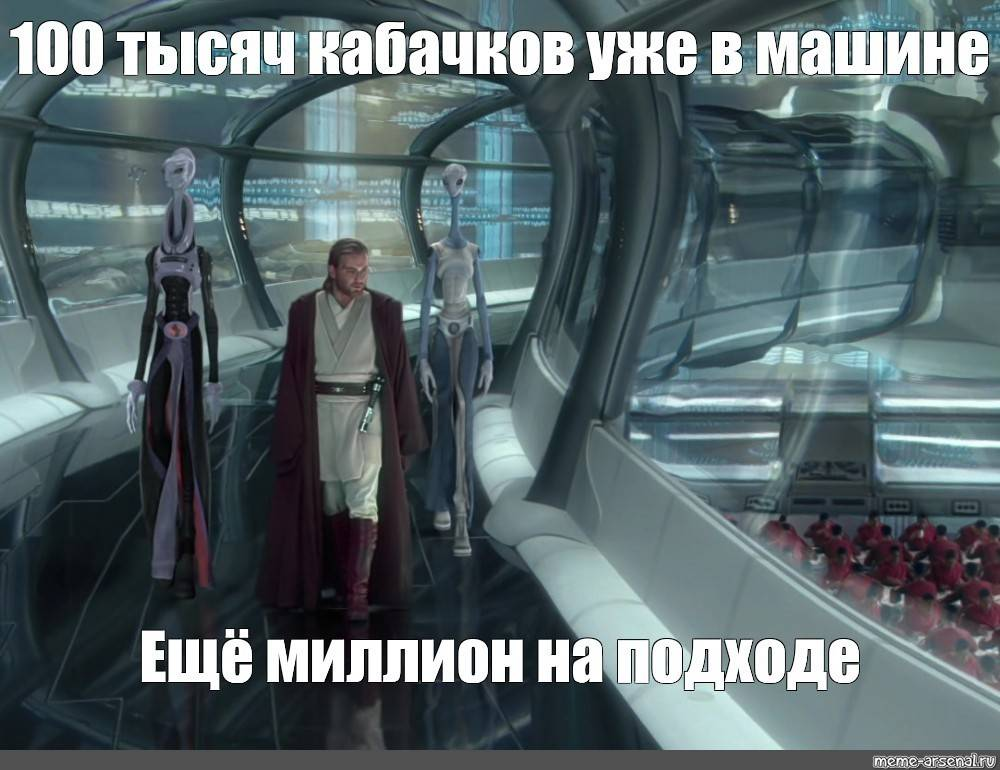

### Содержательная часть

Выбираем четыре числа a, b, c и d таким образом, чтобы все они были различными и ни одно из них $\not= 0\;\;и\;\pm 1$

a = 3/2;
b = 2;
c = 4;
d = 6;

Зададим многоугольник для наглядности линейный преобразований, давайте домик сделаем.

В случае изменения количества точек(параметра n), будет логично перестроить фигуру и уже выбрать на свой вкус. 

Универсальной фигурой можно назвать сетку, например 3х3 = 9 точек.

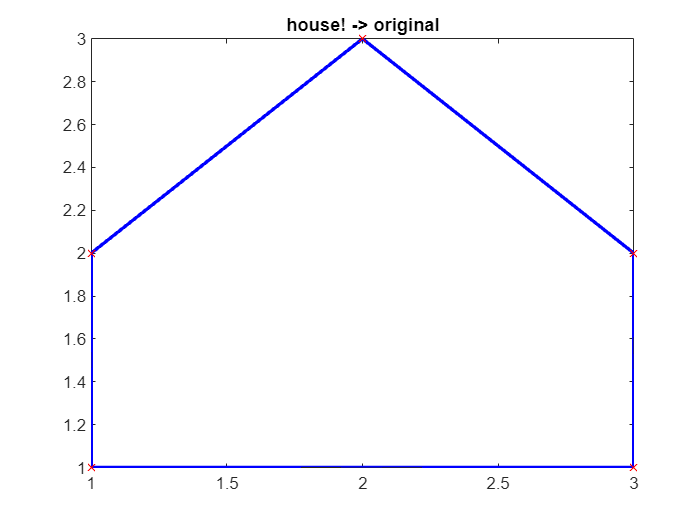

house_coords = [1 1 2 3 3 1;
                1 2 3 2 1 1];
figure(111)
plot(house_coords(1,:), house_coords(2,:), 'b', 'LineWidth', 2);
title('house! -> original')
hold on
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold off

#### 1. Отражение плоскости относительно прямой y=ax

Пользуемся формулой из вступления, и на черновике выбираем произвольную точку, отражаем ее относительно прямой, потом считаем новые координаты.

Но чтобы в формуле выше можно было найти обратную, нужно дописать по вектору справа, теперь можно выразить матрицу преобразования, примерно так:


$$\left\lbrack \begin{array}{cc}
x_{\textrm{new1}}  & x_{\textrm{new2}} \\
y_{\textrm{new1}}  & y_{\textrm{new2}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
* & *\\
* & *
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
x_{\textrm{old1}}  & x_{\textrm{old2}} \\
y_{\textrm{old1}}  & y_{\textrm{old2}} 
\end{array}\right\rbrack \;\;\to \;\left\lbrack \begin{array}{cc}
x_{\textrm{new1}}  & x_{\textrm{new2}} \\
y_{\textrm{new1}}  & y_{\textrm{new2}} 
\end{array}\right\rbrack {\left\lbrack \begin{array}{cc}
x_{\textrm{old1}}  & x_{\textrm{old2}} \\
y_{\textrm{old1}}  & y_{\textrm{old2}} 
\end{array}\right\rbrack }^{-1} =\left\lbrack \begin{array}{cc}
* & *\\
* & *
\end{array}\right\rbrack$$


Для первого и второго отображения сделал скриншот desmos проверки вручную посчитанных двух пар точек преобразований, на их основе уже собираются матрицы old, new и считаем итоговую матрицу преобразований

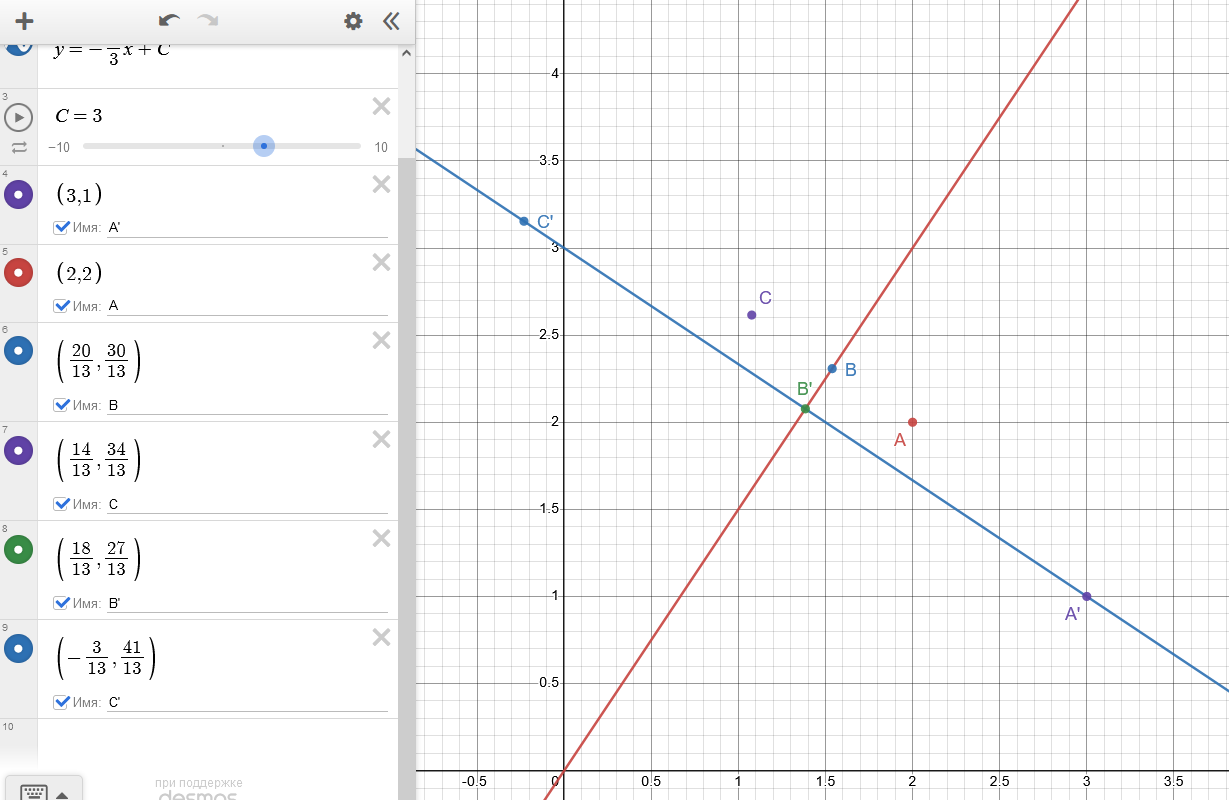

Небольшое спектральное исследование

new1 = [14/13 -3/13;
        34/13 41/13];
old1 = [2 3;
       2  1];
A1 = new1*old1^-1

A1 =    -0.3846    0.9231
    0.9231    0.3846


detA1 = det(A1);
kernel1 = null(A1, 'r') % r = rational базис


kernel1 =

  2×0 empty double matrix



image1 = Image(A1) % см. вспомогательные функции, это вектора линейной оболочки

image1 =    -0.3846    0.9231
    0.9231    0.3846


[V1,D1]=eig(A1) 

V1 =    -0.8321   -0.5547
    0.5547   -0.8321


D1 =    -1.0000         0
         0    1.0000


% где D - диагональная матрица айген_значения, 
% V - айген_вектора, которые можно заметить на графике

Построение графика

x = linspace(0,10,100);
y = a*x;

house_image_coords = A1*house_coords;
figure(3)
plot(x,y, 'b');
title('Отражение относительно прямой y=ax')
xlim([-1 5])
ylim([-1 5])
hold on
grid on
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
hold on 
% Собственные вектора из точки (0, 0)
quiver([0 0], [0 0], V1(1,:),V1(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

#### 2. Отображение всей плоскости в прямую y=bx

Спектральное исследование

new2 = [20/13 18/13;
        30/13 27/13];
old2 = [2 3;
       2 1];
A2 = new2*old2^-1

A2 =     0.3077    0.4615
    0.4615    0.6923


detA2 = det(A2)

detA2 = -2.3058e-16

kernel2 = null(A2, 'r')

kernel2 =    -1.5000
    1.0000


image2 = Image(A2)

image2 =     0.3077
    0.4615


[V2,D2]=eig(A2) 

V2 =    -0.8321    0.5547
    0.5547    0.8321


D2 =    -0.0000         0
         0    1.0000


Построение графика

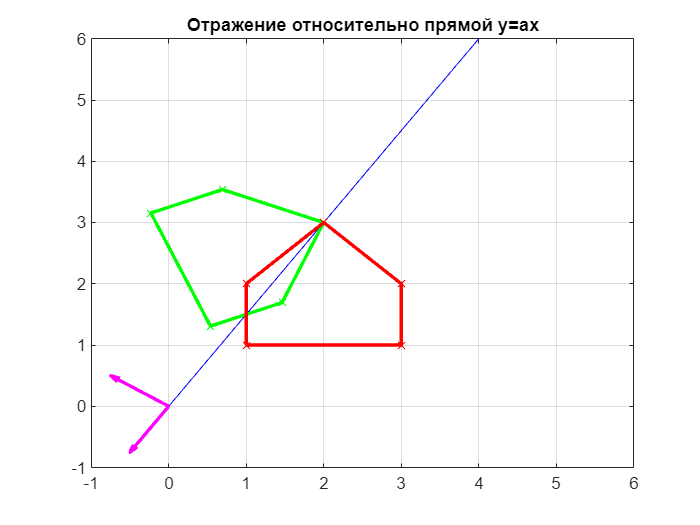

% Строим прямую y=ax
x = linspace(0,4,100);
y = a*x;

house_image_coords = A2*house_coords;

figure(4)
xlim([-1 6])
ylim([-1 6])

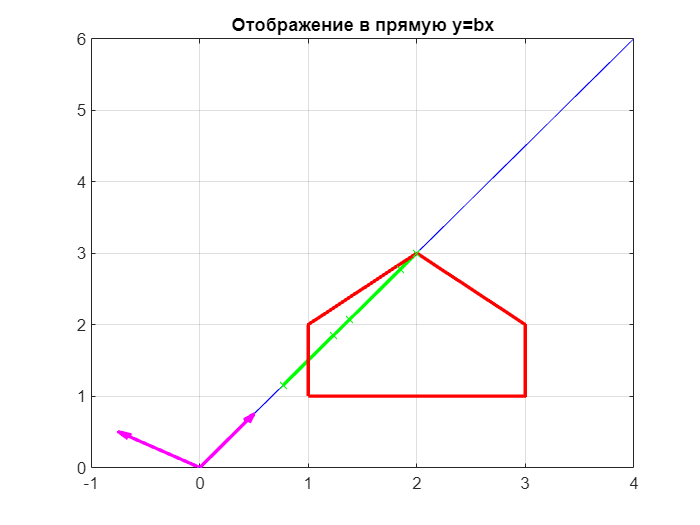

plot(x,y, 'b');
title('Отображение в прямую y=bx')
hold on
grid on
plot(x,y, 'b');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
hold on
quiver([0 0], [0 0], V2(1,:),V2(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

#### 3. Поворот плоскости на 10* против часовой стрелки

Воспользуемся классической матрицей: $R=\;\left\lbrack \begin{array}{cc}
\cos \;\theta  & -\sin \;\theta \\
\sin \;\theta  & \cos \;\theta 
\end{array}\right\rbrack$

deg = 10;
R = -1*[cosd(deg) -sind(deg);
     sind(deg) cos(deg)];

detR = det(R)

detR = -0.7962

kernel3 = null(R, 'r')


kernel3 =

  2×0 empty double matrix



[V3,D3]=eig(R) 

V3 =    -0.9954   -0.0956
   -0.0956   -0.9954


D3 =    -0.9681         0
         0    0.8224


Построение графика

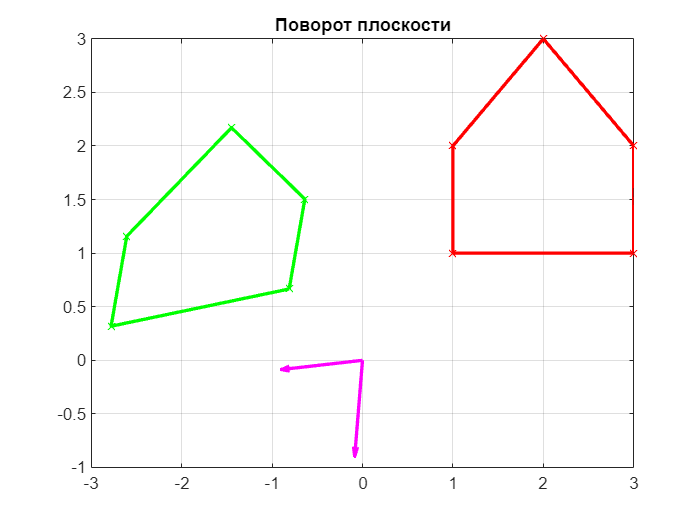

house_image_coords = R*house_coords;
figure(5)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Поворот плоскости')
hold on
grid on
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], V3(1,:),V3(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

#### 4. Центральная симметрия плоскости относительно начала координат

Такое преобразование можно представить в виде инверсии знака у координат, то есть отрицательная единичная матрица:

E = -eye(2);
detE = det(E)

detE = 1


kernel4 = null(E, 'r')


kernel4 =

  2×0 empty double matrix



[V4,D4]=eig(E) 

V4 =      1     0
     0     1


D4 =     -1     0
     0    -1


Строим графики

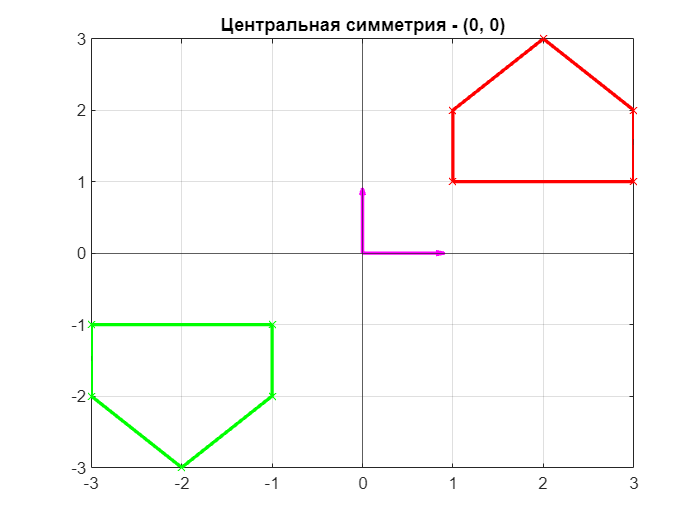


house_image_coords = E*house_coords;
figure(6)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Центральная симметрия - (0, 0)')
xline(0)
yline(0)
hold on
grid on
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], V4(1,:),V4(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

#### 5. Отражение относительно прямой y = ax, потом поворот на $10\degree$ градусов по часовой стрелке

Для этого нам понадобится применить два линейных отображения(в любом порядке), использованных до...

deg2 = -10;
R2 = [cosd(deg2) -sind(deg2);
     sind(deg2) cos(deg2)];

det(A2*R2)

ans = 1.4846e-16

kernel5 = null(E, 'r')


kernel5 =

  2×0 empty double matrix



[V5,D5]=eig(E) 

V5 =      1     0
     0     1


D5 =     -1     0
     0    -1


Построение графиков

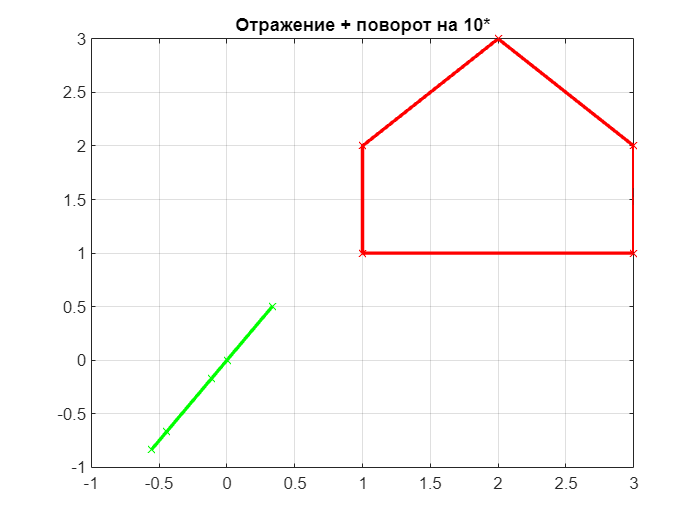

house_image_coords = A2*R2*house_coords;
figure(7)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отражение + поворот на 10*')
hold on
grid on
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold off
hold off

#### 6. Отображение, которое переводит прямую y=0 в y=ax и прямую x=0 в y=bx

Здесь уже два условия отображения, попробуем взять одну точку с соблюдением первого переноса, а вторую - со вторым условием:

(1,0) -> (1, 1.5)    и   (0,1) -> (0.5, 1), соберем на их основе матрицу

*Важно, что точки, не лежащие на y=0 & x=0 перейдут куда-то, наше отображение это не контролирует*

new3 = [1 1/2;
        3/2 1];
old3 = [1 0;
        0 1];
A3 = new3*old3^-1

A3 =     1.0000    0.5000
    1.5000    1.0000


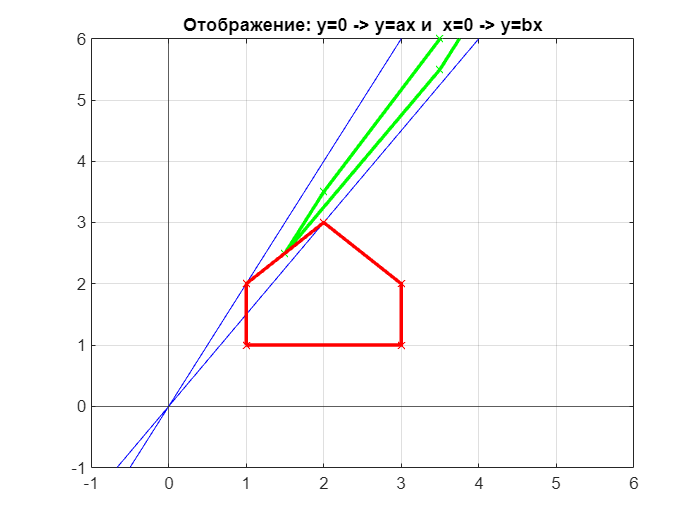


x = linspace(-1,10,100);
y1 = a*x;
y2 = b*x;

house_image_coords = A3*house_coords;
figure(8)
plot(x,y1, 'b');
title('Отображение: y=0 -> y=ax и  x=0 -> y=bx')
xline(0)
yline(0)
xlim([-1 6])
ylim([-1 6])
hold on
plot(x,y2, 'b');
hold on
grid on
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
hold on
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold off

#### 7. Отображение, которое переводит прямую y=ax в y=0 и прямую y=bx в x=0

Обратное от предыдущего, проверил в Command Window на паре точек, чтобы проверить

new3 = [1 1/2;
        3/2 1];
old3 = [1 0;
        0 1];
A4 = A3^-1

A4 =     4.0000   -2.0000
   -6.0000    4.0000


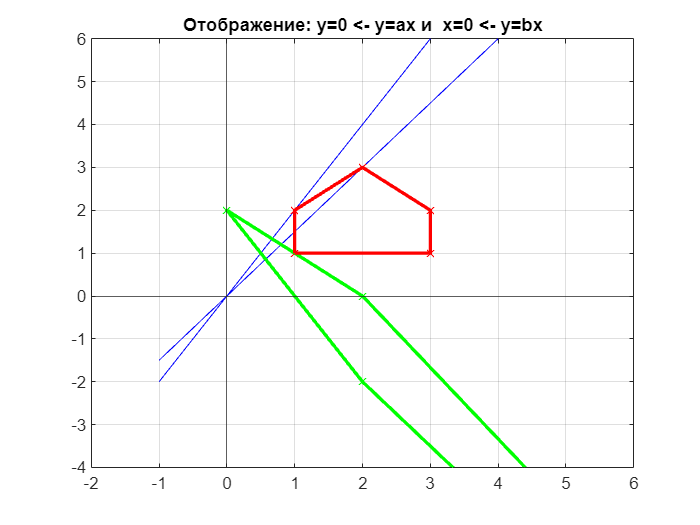


x = linspace(-1,10,100);
y1 = a*x;
y2 = b*x;

house_image_coords = A4*house_coords;
figure(9)
plot(x,y1, 'b');
title('Отображение: y=0 <- y=ax и  x=0 <- y=bx')
xline(0)
yline(0)
xlim([-2 6])
ylim([-4 6])
hold on
plot(x,y2, 'b');
hold on
grid on
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
hold on
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold off

#### 8. Отображение, которое меняет местами прямые y=ax и y=bx

Возьмем по "хорошей" точке от двух прямых, тогда будем примерно следующая перестановка:

(1 3/2) -> (1 2) и (1 2) -> (1 3/2)

На графике хорошо можно заметить переход точек (2 3) -> (2 4) и (1 2) -> (1 3/2)

new8 = [1 1;
        3/2 2];
old8 = [1 1;
        2 3/2];
A8 = new8*old8^-1

A8 =     1.0000         0
    3.5000   -1.0000


detA8 = det(A8);
kernel8 = null(A8, 'r')


kernel8 =

  2×0 empty double matrix



image8= Image(A8)

image8 =     1.0000         0
    3.5000   -1.0000


[V8,D8]=eig(A8) 

V8 =          0    0.4961
    1.0000    0.8682


D8 =     -1     0
     0     1


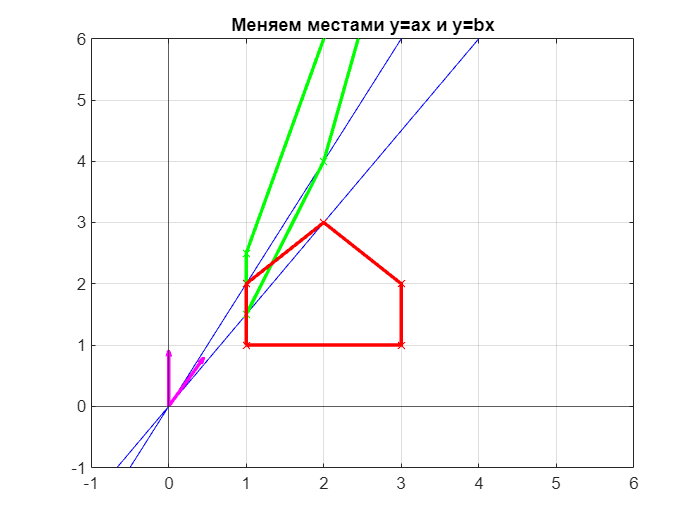

x = linspace(-1,10,100);
y1 = a*x;
y2 = b*x;
house_image_coords = A8*house_coords;

figure(10)
plot(x,y1, 'b');
title('Меняем местами y=ax и y=bx')
grid on
xline(0)
yline(0)
xlim([-1 6])
ylim([-1 6])
hold on
plot(x,y2, 'b');
hold on
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
hold on
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], V8(1,:),V8(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

#### 9. Отображение, которое переводит круг единичной площади с центром в начале координат в круг площади c

Отображение, которое по сути растягивает пространство в "новый_радиус" раз

Возьмем вместо домика другую сетку -> круг радиуса 1 и пару случайных точек внутри него

% Посчитаем радиус нового круга
r = sqrt(c/(2*pi))

r = 0.7979

A10 = [r 0;
      0 r];
% Создаем координаты круга и внутренностей
angles = linspace(0, 2*pi, 50); % 50 точек круга
circle_coords = [cos(angles); sin(angles)];
n = 10; % количество рандомных точек внутри единичного круга
t = 2*pi*rand(n,1);
r = sqrt(rand(n,1));
dots_coords = [transpose(r.*cos(t)); transpose(r.*sin(t))];
circle_image_coords = A10*circle_coords;
dots_image_coords = A10*dots_coords;

Строим графики

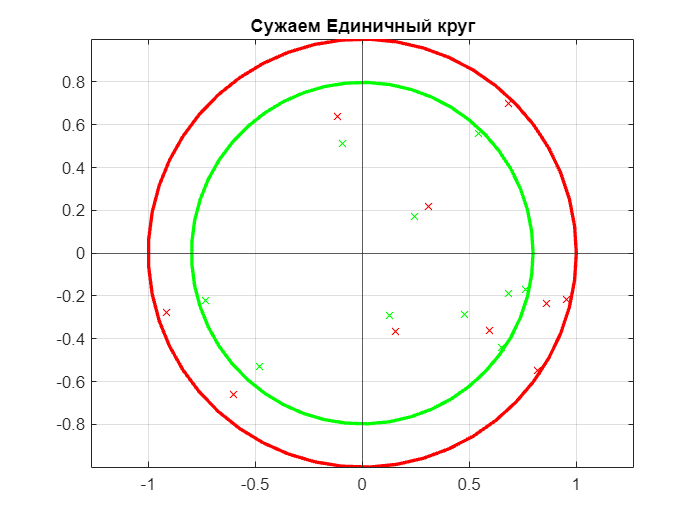

figure(11)
plot(dots_coords(1,:),dots_coords(2,:), 'xr');
title('Сужаем Единичный круг')
xline(0)
yline(0)
axis equal
grid on
hold on
plot(dots_image_coords(1,:),dots_image_coords(2,:), 'xg');
hold on
plot(circle_coords(1,:), circle_coords(2,:), 'r', 'LineWidth', 2);
hold on
plot(circle_image_coords(1,:), circle_image_coords(2,:), 'g', 'LineWidth', 2);
hold off

#### 10. Отображение, которое переводит круг единичной площади с центром в начале координат в **не**круг площади d

Пусть некругом станет эллипс площади d, вспомним формулу его площади


$$S=\pi \textrm{ab}$$


Тогда пусть $a=2\;$, тогда $\;b=\frac{S}{\pi *a}=\frac{d}{\pi *a}$ соответственно

Для построение матрицы отображения вспомним, что эллипс - по сути растянутый круг по Ox и Oy независимо на разный положительный коэффициент, воспользуемся этим, но с коэффициентами a, b

x = 2;
y = d/(pi*x)

y = 0.9549

A10 = [y 0;
       0  x];
x = linspace(-1,10,100);
% Создаем координаты круга и внутренностей
angles = linspace(0, 2*pi, 50); % 50 точек круга
circle_coords = [cos(angles); sin(angles)];
n = 10; % количество рандомных точек внутри единичного круга
t = 2*pi*rand(n,1);
r = sqrt(rand(n,1));
dots_coords = [transpose(r.*cos(t)); transpose(r.*sin(t))];
circle_image_coords = A10*circle_coords;
dots_image_coords = A10*dots_coords;

Строим графики

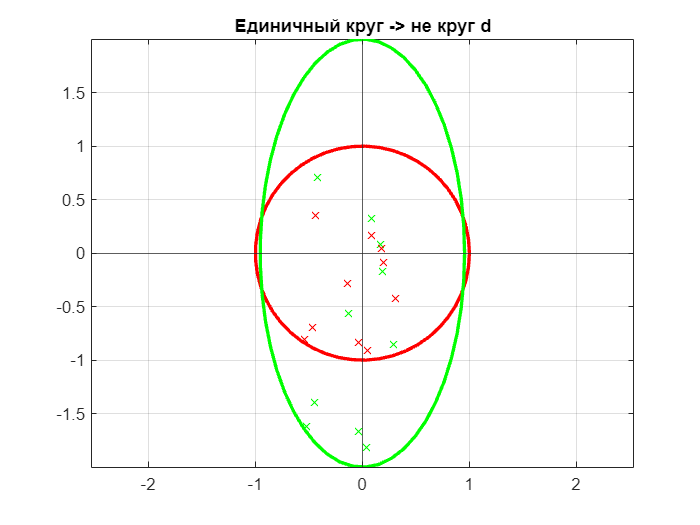

figure(12)
plot(dots_image_coords(1,:),dots_image_coords(2,:), 'xg');
title('Единичный круг -> не круг d')
axis equal 
xline(0)
yline(0)
grid on
hold on
plot(dots_coords(1,:),dots_coords(2,:), 'xr');
hold on
plot(circle_coords(1,:), circle_coords(2,:), 'r', 'LineWidth', 2);
hold on
plot(circle_image_coords(1,:), circle_image_coords(2,:), 'g', 'LineWidth', 2);
hold off

#### 11. Отображение, у которого собственные вектора перпендикулярны, и ни один из них не лежит на прямой y=0 или y=x

A11 = [-1 2;
    2 -1];
detA11 = det(A11)

detA11 = -3

kernel11 = null(A11, 'r')


kernel11 =

  2×0 empty double matrix



[V11,D11]=eig(A11) 

V11 =     0.7071    0.7071
   -0.7071    0.7071


D11 =     -3     0
     0     1


Построение графика

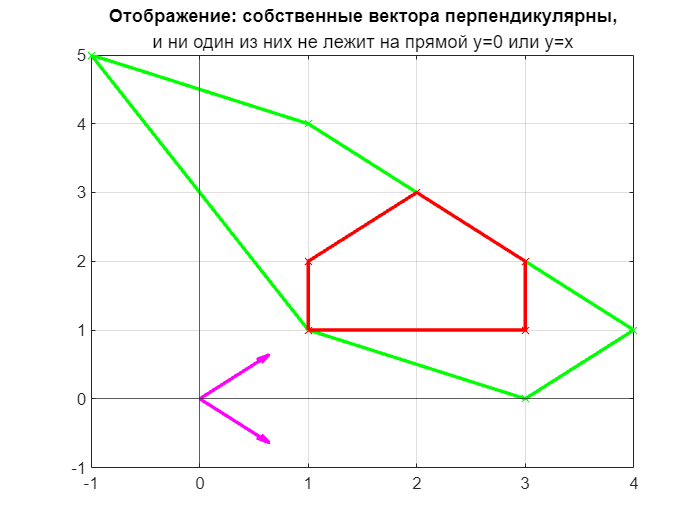

house_image_coords = A11*house_coords;
figure(67)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение: собственные вектора перпендикулярны,','и ни один из них не лежит на прямой y=0 или y=x')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], V11(1,:),V11(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

#### 12. Отображение, у которого нет двух неколлинеарных собственных векторов.

Упрощяя условия, получаем, что нам нужно отображение, что два вектора должны быть коллинеарны здесь, но они тогда будут линейно зависимы, поэтому один из них обязан быть нулевым, а второй - произвольный

A12 = [-1 0;
    2 -1];

detA12 = det(A12)

detA12 = 1

kernel12 = null(A12, 'r')


kernel12 =

  2×0 empty double matrix



[V12,D12]=eig(A12) 

V12 =          0    0.0000
    1.0000   -1.0000


D12 =     -1     0
     0    -1


Построение графика

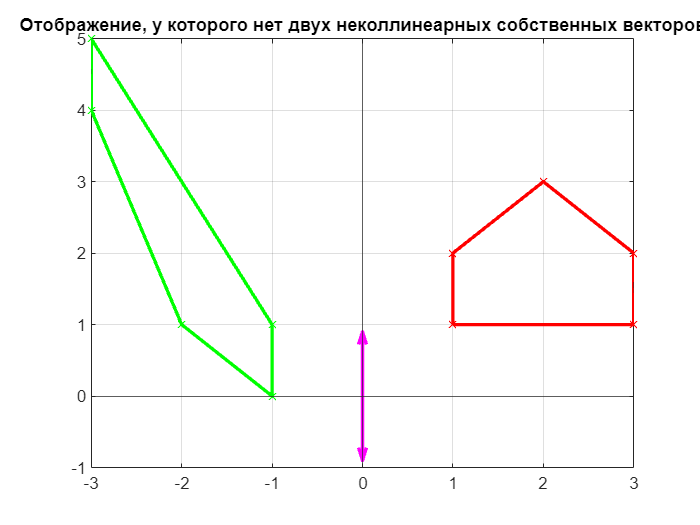

house_image_coords = A12*house_coords;
figure(68)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение, у которого нет двух неколлинеарных собственных векторов')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], V12(1,:),V12(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

#### 13. Отображение, у которого нет ни одного вещественного собственного вектора (но при этом само отображение задаётся вещественной матрицей).

Подойдет такая матрица поворота. Для разнообразия домножим  на константу, чтобы еще и растянуть пространство бонусом

R13 = 0.4* [0 2;
           -1 0];
image13 = Image(R13)

image13 =          0    0.8000
   -0.4000         0


detR13 = det(R13)

detR13 = 0.3200

kernel13 = null(R13, 'r')


kernel13 =

  2×0 empty double matrix



[V13,D13]=eig(R13) 

V13 =    0.8165 + 0.0000i   0.8165 + 0.0000i
   0.0000 + 0.5774i   0.0000 - 0.5774i


D13 =    0.0000 + 0.5657i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 0.5657i


Построение графика

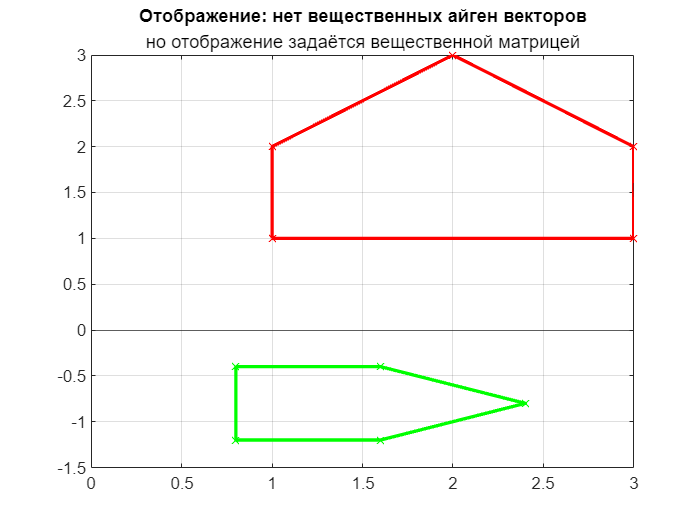

house_image_coords = R13*house_coords;
figure(69)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение: нет вещественных айген векторов','но отображение задаётся вещественной матрицей')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold off

#### 14. Отображение, для которого любой ненулевой вектор является собственным

Логично предположить, что эта должна быть матрица, возвращающая тот же вектор, то есть единичная

k = 0.2;
A14 = k*eye(2)

A14 =     0.2000         0
         0    0.2000


detA14 = det(A14)

detA14 = 0.0400

image14 = Image(A14)

image14 =     0.2000         0
         0    0.2000


kernel14 = null(A14, 'r')


kernel14 =

  2×0 empty double matrix



[V14,D14]=eig(A14) 

V14 =      1     0
     0     1


D14 =     0.2000         0
         0    0.2000


Построение графика

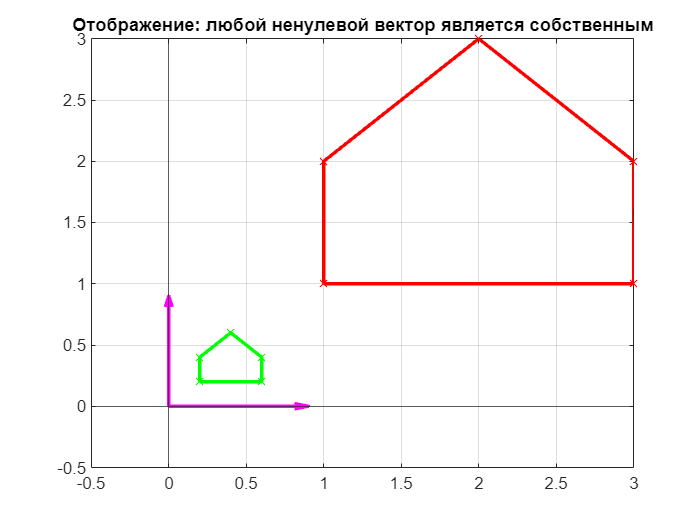

house_image_coords = A14*house_coords;
figure(70)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение: любой ненулевой вектор является собственным')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], V14(1,:),V14(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

#### 15. Пару отображений, последовательное применение которых даёт различные результаты в зависимости от порядка: AB != BA

Так как матрицы в общем случае не коммутативные, то можем себе позволить взять произвольные А,B, предврательно перемножив их, чтобы навсякий проверить:

A15 = [3 -1; 1 0];
B15 = [0 2; 1 2];
A15*B15

ans =     -1     4
     0     2


B15*A15 % дефствительно, разные...

ans =      2     0
     5    -1


[VA15,DA15]=eig(A15) 

VA15 =     0.9342    0.3568
    0.3568    0.9342


DA15 =     2.6180         0
         0    0.3820


[VB15,DB15]=eig(B15) 

VB15 =    -0.9391   -0.5907
    0.3437   -0.8069


DB15 =    -0.7321         0
         0    2.7321


[VAB15,DAB15]=eig(A15*B15) 

VAB15 =     1.0000    0.8000
         0    0.6000


DAB15 =     -1     0
     0     2


[VBA15,DBA15]=eig(B15*A15) 

VBA15 =          0    0.5145
    1.0000    0.8575


DBA15 =     -1     0
     0     2


Построение графиков

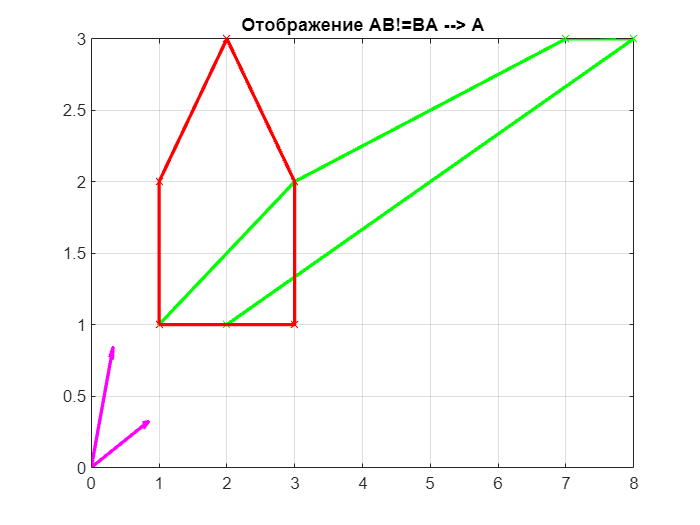

%--А--%
house_image_coords = A15*house_coords;
figure(71)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение AB!=BA --> A')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], VA15(1,:),VA15(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

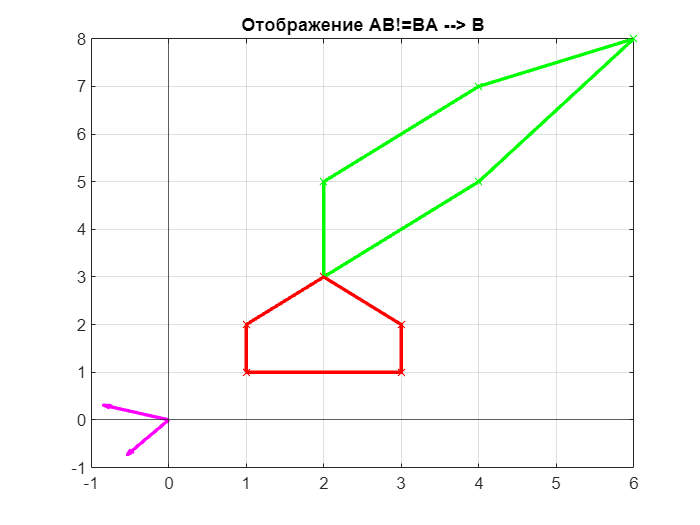

%--B--%
house_image_coords = B15*house_coords;
figure(72)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение AB!=BA --> B')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], VB15(1,:),VB15(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

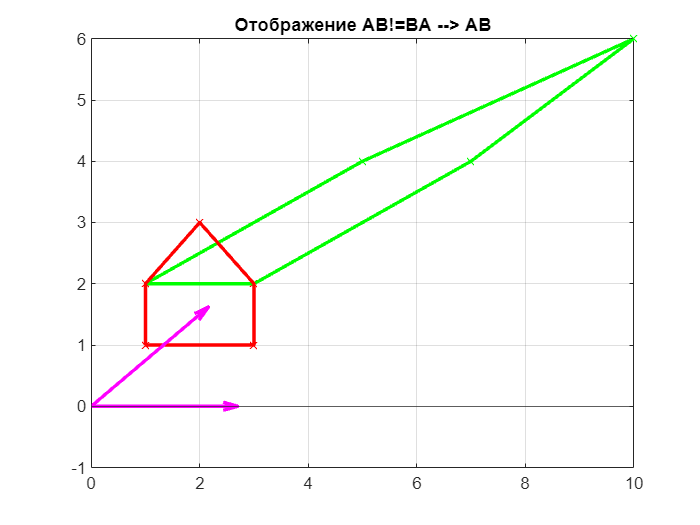

%--АB--%
house_image_coords = A15*B15*house_coords;
figure(73)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение AB!=BA --> AB')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], VAB15(1,:)*3,VAB15(2,:)*3,'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 

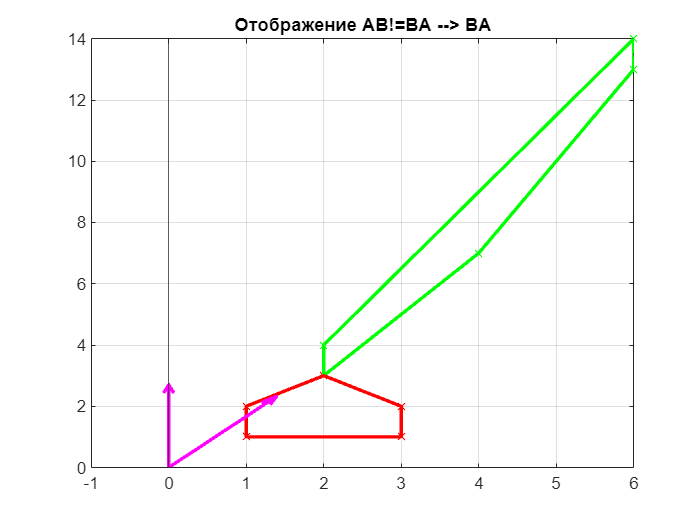

%--BА--%     
house_image_coords = B15*A15*house_coords;
figure(74)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение AB!=BA --> BA')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], VBA15(1,:)*3,VBA15(2,:)*3,'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 

#### 16. Пару отображений, последовательное применение которых даёт одинаковый результат независимо от порядка: AB=BA

Очевидным примером может послужить: поворот+расширение

Поиграем с произвольностью операций, запишем умножение матриц в общем виде с двух сторон:


$$\begin{array}{l}
\left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
e & f\\
g & h
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\textrm{ae}+\textrm{bg} & \textrm{af}+\textrm{bh}\\
\textrm{ce}+\textrm{dg} & \textrm{cf}+\textrm{dh}
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
e & f\\
g & h
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\textrm{ae}+\textrm{fc} & \textrm{ae}+\textrm{fb}\\
\textrm{ga}+\textrm{hc} & \textrm{gb}+\textrm{hd}
\end{array}\right\rbrack 
\end{array}$$


Начав с равенства $\textrm{ae}+\textrm{bg}=\textrm{ae}+\textrm{fc}$ подставляем произвольные числа и молимся, чтобы все это сошлось на последней клетке. 

Но давайте просто автоматизируем этот процесс :)

С помощью функции генерируем пары коммутирующих матриц, пока не выпадут максимально не похожие друг на друга пары, в моем случае это...

% [A16,B16] = generateCommutative()
A16 = [-2 3; 9 1];
B16 = [1 1; 3 2];
% проверяем, потому что матлаб может выдать странные пары
A16*B16

ans =      7     4
    12    11


B16*A16

ans =      7     4
    12    11


[VA16,DA16]=eig(A16) 

VA16 =    -0.6089   -0.3983
    0.7933   -0.9172


DA16 =    -5.9083         0
         0    4.9083


[VB16,DB16]=eig(B16) 

VB16 =    -0.6089   -0.3983
    0.7933   -0.9172


DB16 =    -0.3028         0
         0    3.3028


[VAB16,DAB16]=eig(A16*B16) 

VAB16 =    -0.6089   -0.3983
    0.7933   -0.9172


DAB16 =     1.7889         0
         0   16.2111


[VBA16,DBA16]=eig(B16*A16) 

VBA16 = 2×2
   -0.6089   -0.3983
    0.7933   -0.9172


DBA16 = 2×2
    1.7889         0
         0   16.2111


Построение графиков

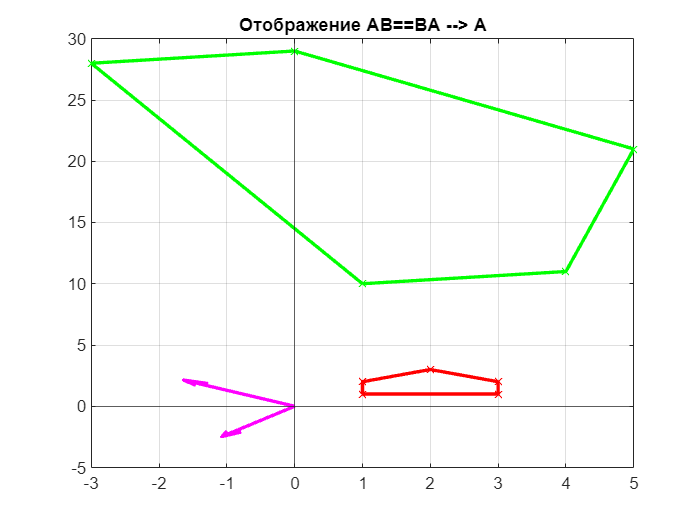

%--А--%
house_image_coords = A16*house_coords;
figure(75)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение AB==BA --> A')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], VA16(1,:)*3,VA16(2,:)*3,'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

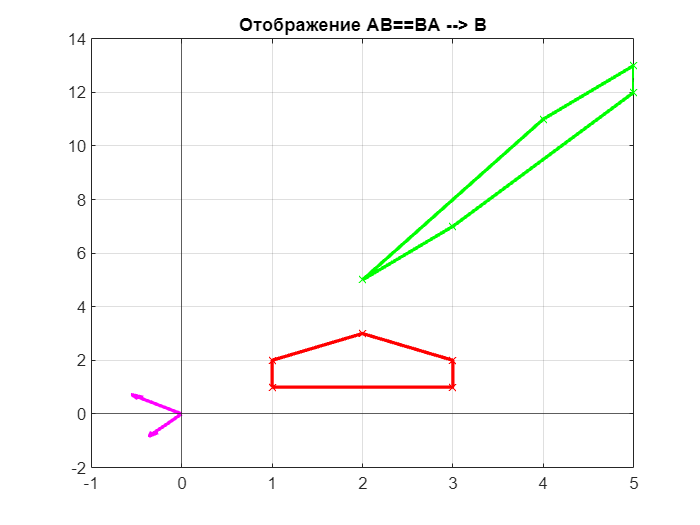

%--B--%
house_image_coords = B16*house_coords;
figure(76)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение AB==BA --> B')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], VB16(1,:),VB16(2,:),'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 
hold off

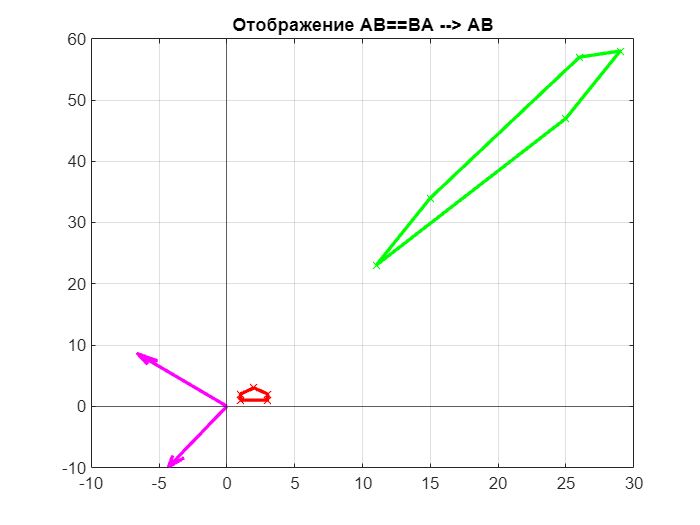

%--АB--%
house_image_coords = A16*B16*house_coords;
figure(77)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение AB==BA --> AB')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], VAB16(1,:)*12,VAB16(2,:)*12,'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 

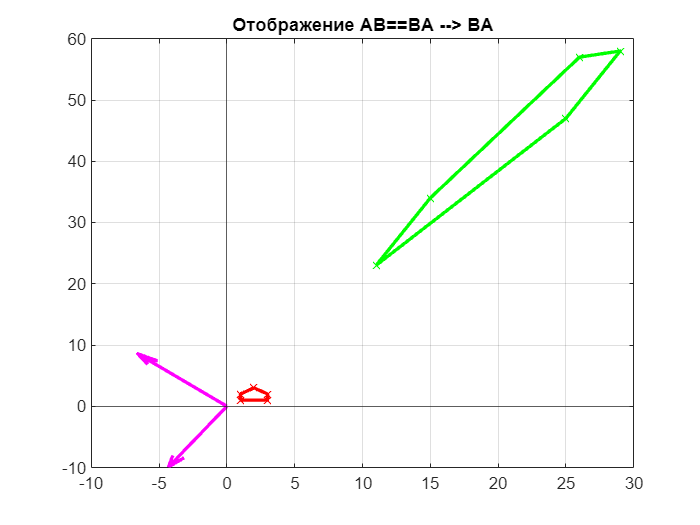

%--BА--%     
house_image_coords = B16*A16*house_coords;
figure(78)
plot(house_image_coords(1,:),house_image_coords(2,:), 'xg');
title('Отображение AB==BA --> BA')
hold on
grid on
xline(0)
yline(0)
plot(house_coords(1,:),house_coords(2,:), 'xr');
hold on
plot(house_image_coords(1,:), house_image_coords(2,:), 'g', 'LineWidth', 2);
hold on
plot(house_coords(1,:), house_coords(2,:), 'r', 'LineWidth', 2);
hold on
quiver([0 0], [0 0], VBA16(1,:)*12,VBA16(2,:)*12,'m','LineWidth', 2, 'MaxHeadSize', ...
    0.3,'MaxHeadSize', 0.3) 

Поздравляю, вы выдержали небольшое испытание матлабом...

### 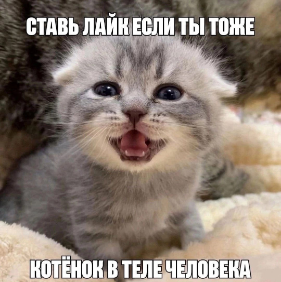

### По поводу симметричных матриц в отображениях

Вспомним, что симметричные матрицы имеют следующие свойства:

- Всегда имеют только вещественные айген значения

- Имеют ортогональные айген векторы, которые соответствуют различным айген значениям

- Логично предположить, что симметричная матрица задает симметричное преобразование

Поэтому подойдут любые отображения со словом "симметрия" - это пункт 1,2,3(тригонометрическое),4

5-й пункт включает в себя композицию двух отображений - растяжение(который все портит) + поворот, не подходит нам 

Отображение, задаваемыми диагональными матрицами -> 9,10 пункт, с кругами, тоже подойдут

В последующих пунктах симметричная матрица не может быть в общем случае

### Вспомогательные функции и их описание

**Поиск образа матрицы путем "приведенного ступенчатого вида"**

Результат - является линейной оболочкой натянутой на базисные вектора ниже

function range = Image(A)
    range=[];
    r = rank(A);
    gaussian= rref(A);
    for i=1:2
        if all(gaussian(:,i) == 0 | gaussian(:,i) == 1)
            if size(range,2)<r
                range =[range A(:, i)];
            end
        end
    end
end

Генерируем коммутирующую матрицу к заданной

function [m1,m2] = generateCommutative()
    m1 = zeros([2,2]);
    m2 = zeros([2,2]);
    while true
        m1= randi([-10 10], 2, 2);
        m2= randi([-10 10], 2, 2);
        if isequal(m2*m1,m1*m2) && isreal(eig(m2)) && isreal(eig(m1))
            break
        end
    end
end
